# Basic Diffusion Tensor Imaging with dmrimatlab

In the previous chapter we reviewed the basics of each type of diffusion-related volume but, how can we get one kind of signal representation from the raw diffusion data? In this chapter we will start with the simplest one, i.e. the diffusion tensor representation. Hence, we will take an "attenuation volume", whose 4-th dimension stacks all the channels acquired for different gradient directions and b-values, and end-up with a "tensor volume", whose 4-th dimension has the 6 different components of the diffusion tensor.

***TO DO: ***Clear all variables and figures to start from zero (*Ctrl+ENTER*):

clear;
close('all');

## 1. Prepare the data

***BEFORE WE PROCEED***:

- Note we need, at the very least, the attenuation signal and the minimal information to intepret it (i.e. the gradients table and b-values). Let's load a test volume (*Ctrl+ENTER*):

whos -file test_data.mat
% The minimum required information is: the attenuation signal atti, the
% gradients table gi and the b-values bi. Note their sizes mast match.
% Additionally, an optional mask whose field of view matches that of atti
% is useful to avoid unnecessary computations. Load them all:
load test_data.mat

- The tensor model is a very simple one, and can explain only certain macroscopic effects of diffusion. In practice, this means that DTI is not usable for b-values over $2,000 s/mm^2$. Don't forget this important issue if you work with multi-shell data. Let's fix it:

unique(bi)',
% There are values not suitable for DTI
bcut = 2000; % This should be the maximum value used for DTI
usable = (bi<=bcut);
atti = atti(:,:,:,usable);
gi = gi(usable,:);
bi = bi(usable,1);
size(gi),
size(bi),
size(atti),
% The dimensions still match...

## 2. Estimate the diffusion tensor

Now we are ready to estimate the diffusion tensor with the proper function. The expected input is an attenuation volume, and the expected output is a DTI volume. Hence, the function is named `atti2dti` (*Ctrl+ENTER*):

% atti, gi and bi are the minimum required information, and therefore they
% are mandatory inputs that are passed as "positional arguments". All other
% input arguments are optional and are passed as 'key', value pairs:
tic;
dti = atti2dti( atti, gi, bi, ...
    'mask', mask, ...
    'wls', false, ...
    'nonlinear', false );
fprintf(1,'It took %1.3f seconds to estimate the diffusion tensor\n',toc);

***QUIZ:***

*What is the meaning of the *`'wls'`* and *`'nonlinear'`* optional arguments? Try to change their values (*`false/true`*) and check the effects on the computation times. Also, try to avoid using the mask (just remove the key/value pair from the input arguments) and check the computation times.*

## 3. Estimate the spectrum of the diffusion tensor

The DTI volume we have just estimated stacks the 6 free components of the diffusion tensor in its 4-th component (*Ctrl+ENTER*):

size(dti),

However, these 6 number are difficult to interpret even if they are re-arranged into the $3\times3$matrix that representes the diffusion tensor. To properly infer the actual diffusion properties of each voxel, we need to compute:

- The 3 eigenvectors of the diffusion tensor, which provide the 3 main spatial directions along which diffusion occurs.

- The 3 eigenvalues of the diffusion tensor, which provide the amount of diffusion (in $mm^2/s$) along each of these directions.

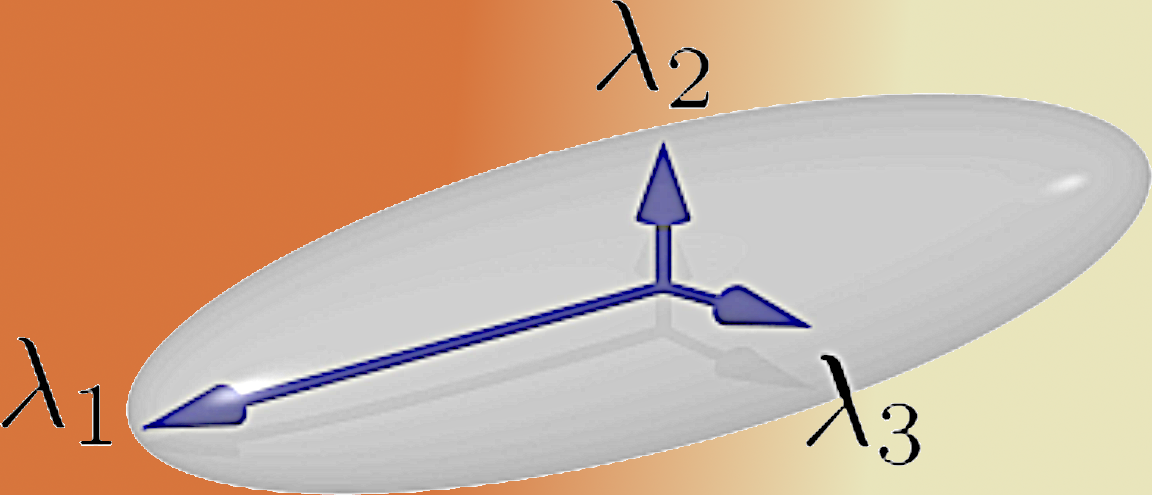

The three eigenvalues and the three eigenvectors make up the "spectrum" of the diffusion tensor. To compute it, we will use a function whose expected input is a DTI volume and whose expected output is the spectrum of the diffusion tensor. Hence, the name of the function is `dti2spectrum`:

% The one and only required input is the DTI volume itself, which is the
% first positional argument. All other arguments are optional and are 
% passed as 'key', value pairs:
[u1,u2,u3,l1,l2,l3] = dti2spectrum( dti, ...
    'mask', mask );

`u1`, `u2` and m are the eigenvectors (unit-norm vectors with 3 components that are stored in the 4-th dimension of each of the arrays), meanwhile `l1`, `l2` and `l3` are the (scalar) eigenvalues:

size(u1), size(u2), size(u3),
size(l1), size(l2), size(l3),

We can have an idea of the values of `l1`, `l2` and `l3` by computing their histograms over the masked region:

close(figure(1));
hf1 = figure(1);
colors = eye(3)/2;
hold('on');
hk = zeros(1,3);
for k=1:3
    lk = eval(sprintf('l%d',k));
    hk(k) = histogram( lk(mask), ...
        'EdgeAlpha', 0.5, 'FaceColor', ...
        colors(k,:), 'FaceAlpha', 0.4 );
end
axs = axis;
axis([-0.001,0.004,axs(3),axs(4)]);
legend(hk,'\lambda_1','\lambda_2','\lambda_3','Location','NorthEast');
xlabel('Amount of diffusion [mm^2/s]');
ylabel('Counts');

Some things to note:

- The convention is ordering the eigenvalues in descending order, so that $\lambda_1$ is the largest one and therefore $u_1$ is the principal diffusion direction

- Theoretically, the amount of diffusion should range from 0 to $3.0\cdot10^{-3} mm^2/s$, which is the diffusivity of free water at body temperature. However, due to noise and degeneracies the estimation procedure can yield out-of-range values.

***QUIZ:***

*Go back to section 2, play around with different combinations of the optional arguments *`'wls'`* and *`'nonlinear'`* and run again this section afterwards to check the effect of these combinations on the diffusivities computed.*

## **4. Represent diffusion tensor-based quantitative information**

Of course, we can represent the raw eigenvalues in an anatomical map to check their coherence. For example, for the largest one (*Ctrl+ENTER*):

close(figure(2));
hf2 = figure(2);
set(hf2,'Position',[1,1,1200,400]);
plotSlicedVolume( hf2, l1, mask ); % This function is coded below
title('Main eigenvector');

As you can see, the maps ara natomically coherent, and the maximum amount of diffusivity corresponds, obviously, to the cerebrospinal fluid inside the ventricles.

What about the other eigenvalues? We could, of course, repeat the plot for them. Or we could rather observe their joint behavior by representing their mean and their variability. Well, this "mean" and (normalized) "variability" of the three eigenvalues are what we call, respectively, the "Mean Diffusivity" and the "Fractional Anisotropy" of the diffusion tensor at each voxel. These two scalar measures are computed from the spectrum of the diffusion tensor, hence we will use a function named `spectrum2scalar`:

% We need the three eigenvalues (note we do not need the eigenvectors) to
% compute them:
MD = spectrum2scalar(l1,l2,l3,'mask',mask,'scalar','md');
FA = spectrum2scalar(l1,l2,l3,'mask',mask,'scalar','fa');
close(figure(3));
hf3 = figure(3);
set(hf3,'Position',[1,1,1200,400]);
plotSlicedVolume( hf3, MD, mask );
title('Mean Diffusivity');
close(figure(4));
hf4 = figure(4);
set(hf4,'Position',[1,1,1200,400]);
plotSlicedVolume( hf4, FA, mask );
title('Fractional Anisotropy');

These two scalar measurements are the ones most used in practice. Note that the MD has the same scale as the eigenvalues themselves, ranging from 0 to the free-water diffusivity at body temperature ($3.0\cdot10^{-3} mm^2/s$). The FA, on the contrary, is a normalized variance, ranging from 0 to 1 (though outliers greater than 1 might appear if negative eigenvalues are present):

close(figure(5));
hf5 = figure(5);
histogram( FA(mask), 'EdgeAlpha', 0.5, ...
    'FaceColor', [.0,.0,.5], 'FaceAlpha', 0.4);
xlabel('Fractional Anisotropy values');
ylabel('Counts');

***QUIZ:***

*Go back to section 2, play around with different combinations of the optional arguments *`'wls'`* and *`'nonlinear'`* and run again sections 3 and 4 afterwards to check the effect of these combinations on the FA computed.*

Note that the FA is large inside the white matter and small in the gray matter. Indeed, the value of the FA is usually thresholded to segment the white matter.

***QUIZ:***

*What other scalar measurements can be computed from the eigenvalues of the diffusion tensor and what are their meanings? Can you represent some of them? ****HINT: ****Check the function *`spectrum2scalar`*.*

## 5. Represent directional information

Up to this point we have used only the eigenvalues (amount of diffusion along each axis) of the diffusion tensor, but we have completely neglected the direction information, i.e. the eigenvectors of the tensor. Is there an easy way to represent directional information? The answer is yes, through color-coding.

Color-coded maps embed the three components of the main eigenvector (`u1`, according to our convention) in the three channels of an RGB image, so that **red** prevails for voxels with meso-structures aligned with the `'x'` axis, **green** prevails for voxels with meso-structures aligned with the `'y'` axis and **blue** prevails for voxels with meso-structures aligned with the `'z'` axis. Remember that diffusion sequences cannot tell the positive orientation of one axis (e.g. `'x'`) from the negative one. Besides, the brightness of each voxel is weighted by its FA to improve visualization and remove low-anisotropy noise-like voxels.

The color-coded image is obtained from the spectrum of the diffusion tensor, hence the function to use is called `spectrum2colorcode `(*Ctrl+ENTER*):

% We need the main eigenvector to extract the RGB channels, and also the
% three eigenvalues to compute the FA and weight the brightness of each
% voxel:
colored = spectrum2colorcode(u1,l1,l2,l3,'mask',mask);
% The first three dimensions are the field of view, and the 4-th one, with
% size 3, contains the 3 channels R, G and B:
size(colored),
% Plot the results:
close(figure(6));
hf6 = figure(6);
set(hf6,'Position',[1,1,1200,400]);
plotSlicedVolume( hf6, colored, mask );
title('Color-coding');

***QUIZ:***

*Can you identify the big bright, magenta structure right in the middle of the fourth slice? And the four bright green spots that surround it? Why do they have these colors?*

## 6. Some other representations?

If you are familiar with Diffusion Tensor Imaging, or you have ever felt curious about it, it is likely that you have found fancy pictures with plots of nerve fibers or the diffusion ellipsoids themselves placed at each voxel:

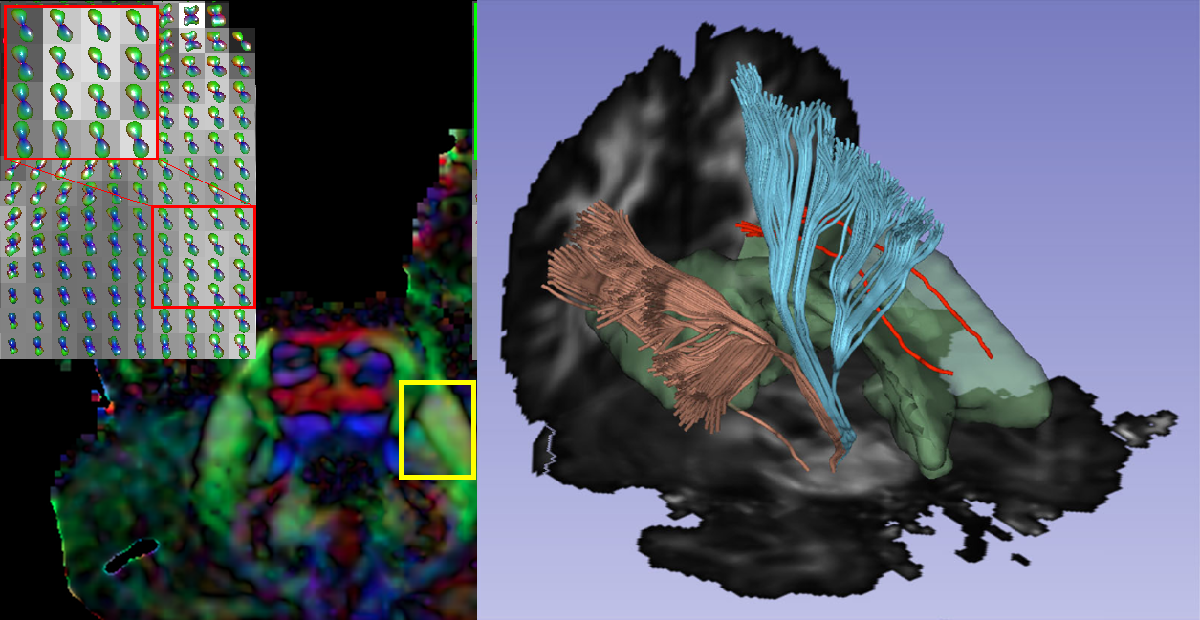

So, can `dmrimatlab` make this kind of plots? The answer is yes: `dmrimatlab` is able to compute and represent glyphs, and it also integrates several types of simple and advanced tractography algorithms. However, we will come back over this[ in the last chapter](matlab:open('./WCP_Representations_06.mlx')).

[Go back to index page](matlab:open('./IndexWorkshopWCP.mlx'))

[Previous](matlab:open('./WCP_Data_02.mlx'))

[Next](matlab:open('./WCP_FWVF_04.mlx'))

## Auxiliar functions

Don't worry too much about this section. It is just a shortcut to represent sliced volumes with just one call to a function, so that the main code remains as clean as possible:

function plotSlicedVolume(hf,volume,mask)
figure(hf);
slices = [3,5,8,10,13,15]; % Slices to show
tiledlayout( 1, length(slices), 'TileSpacing', 'none' );
for k=1:length(slices)
    nexttile;
    img = squeeze(volume(:,:,slices(k),:));
    % Transpose the image (swap xy -> ji) to meet Matlab
    % convention:
    img = permute(img,[2,1,3]);
    if(size(img,3)>1)
        % If the images is RGB, represent as it is:
        imshow(img);
    else
        % Otherwise, find a proper dynamic range:
        window = quantile( volume(mask), [0.01,0.99] );
        % And plot:
        imshow(img,window);
        if(k==length(slices))
            colorbar;
        end
    end
end
drawnow;
end